## Signal Generation

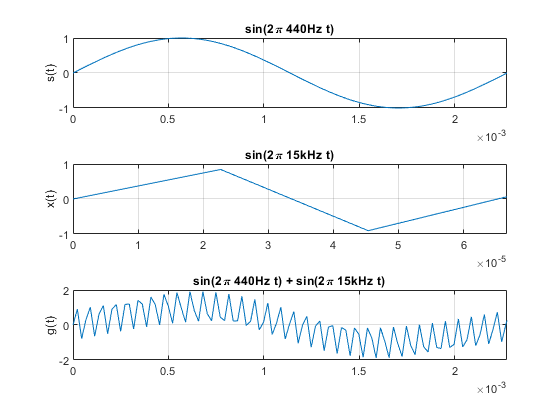

T = 1; % Specify time duration of the signal
f1 = 440; 
f2 = 15e3;
fs = 44.1e3; % Sampling time of the signal
t = [0:1/fs:T]; % 

s = sin(2*pi*f1*t); % 440 Hz signal
x = sin(2*pi*f2*t); % 15kHz signal
g = s + x; % combined signal

subplot(3,1,1) % 440 Hz sinusoidal signal
plot(t, s)
title('sin(2\pi 440Hz t)')
ylabel('s(t)')
xlim([0 1/f1])
grid on;

subplot(3,1,2) % 15kHz sinusoidal signal
plot(t, x)
title('sin(2\pi 15kHz t)')
ylabel('x(t)')
xlim([0 1/f2])
grid on;

subplot(3,1,3) % combined signal of x + s
plot(t, g)
title('sin(2\pi 440Hz t) + sin(2\pi 15kHz t)')
ylabel('g(t)')
xlim([0 1/f1])
grid on;

## Frequency components of g(t) = x(t) + s(t)

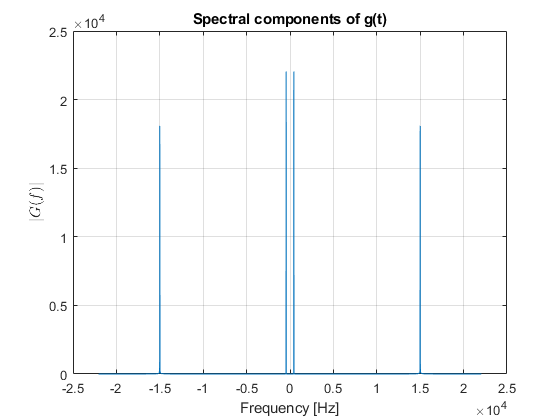

[G, f] = fouriert(g, t);
figure;
plot(f, abs(G))
title('Spectral components of g(t)')
xlabel('Frequency [Hz]')
ylabel('$\vert G(f) \vert$', 'Interpreter','latex')
grid on;

## Generate Lowpass FIR Filter

- Fpass = 500;    % Passband Frequency

- Fstop = 600;    % Stopband Frequency

- Apass = 1;       % Passband Ripple (dB)

- Astop = 60;      % Stopband Attenuation (dB)

- Fs = 44100;     % Sampling Frequency

LPF = getLPF(); % Generate the coefficients of the Lowpass filter with a Fstart = 500Hz & Fstop = 1000Hz 

## Obtain the frequency response of the filter

- Reshape the outputs (previously 88201 x 1) to [1 88201] to prepare for filtering  

n = length(t);
[h, th] = impz(Hlp, n, fs);
h = reshape(h, [1 n]);
th = reshape(th, [1, n]);
[G, f] = fouriert(h, th);
plot(f, abs(G));
xlim([0, 1000]);

## Filter signal and plot results

[y, ty] = linfilt(h, th, g, t);
[G, f] = fouriert(y, ty);
plot(f, abs(G));
title('Lowpass FIR output')
xlabel('Frequency [Hz]')
ylabel('$\vert G(f) \vert$', 'Interpreter','latex')
grid on;

dc_shift = g + abs(min(g));
sig_vals = int32(2^ceil(log2(length(t))) * (dc_shift / max(dc_shift)));
FID = fopen('signal_generator_values.txt', 'w');
for ii = 0:length(t)-1
    fprintf(FID, "17\'d%i: sine = 17\'d%i;\n", ii, sig_vals(ii + 1));
end
fclose(FID);

oscope_signal = csvread('195kHz_signal.csv');
t_oscope_signal = [0:40e-9:dt*length(oscope_signal) - dt];
plot(t_oscope_signal, oscope_signal);
grid on;

figure;